# **Tutorial 7**: Cantilevered plate dynamics studied with SDTlib blocks: `NINOP Nastran body, FEM Kirchhoff plate, Kirchhoff plate super-element `( $\approx 2\;mn$ run)

*by D. Alazard and F. Sanfedino - ISAE-SUPAERO*

## 1. Description

(this tutorial has an animation at the end of this live script)

In this tutorial we shown how to directly use the results coming from `NASTRAN` modal analysis to build a NINOP model in the `SDTlib`.

A NINOP model of a bending plate $\mathcal P$ is taken as appication example.

Let consider the `PATRAN` model in the next figure:

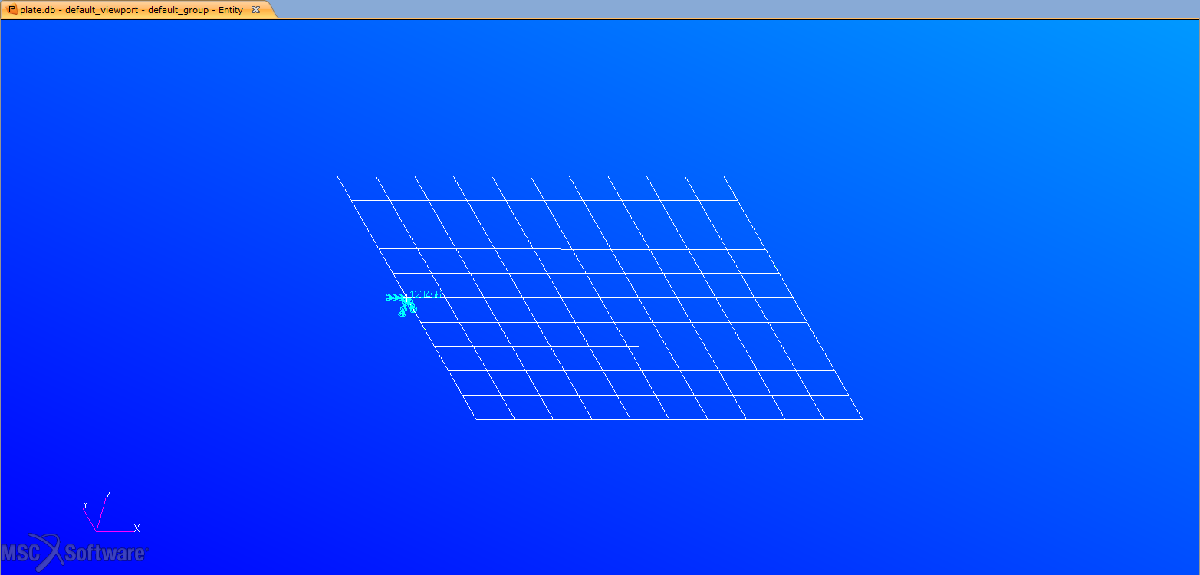

A squared plate of $1\,m$ size is meshed with $10$ elements CQUAD4 per side. See `fbdf_plate.bdf` file for details on mechanical properties. The total number of nodes is the 121.

This plate is blocked (all 6 DOF) in the node P. All the other nodes are left free.

NASTRAN SOL 103 routine provides the result of the modal analysis like in the next figure for the first mode:

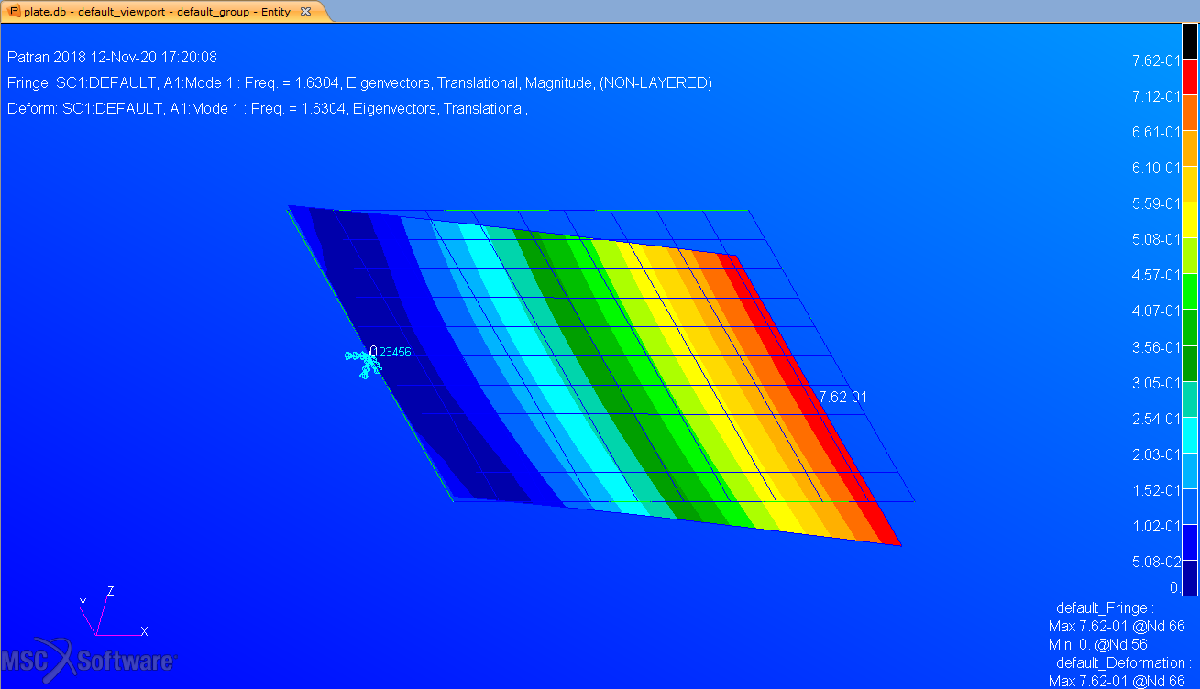

## 2. Importing the NASTRAN model in SDTlib

We want now to build the NINOP model of this structure by recovering the dynamic model at the 9 nodes showed in the next figure representating the plate in the plane $(P,\;\mathbf x_p,\;\mathbf y_p)$ of the plate body frame $\mathcal R_p$. Note that the corresponding node index (N.B. the indexes are the same as in the PATRAN mesh).

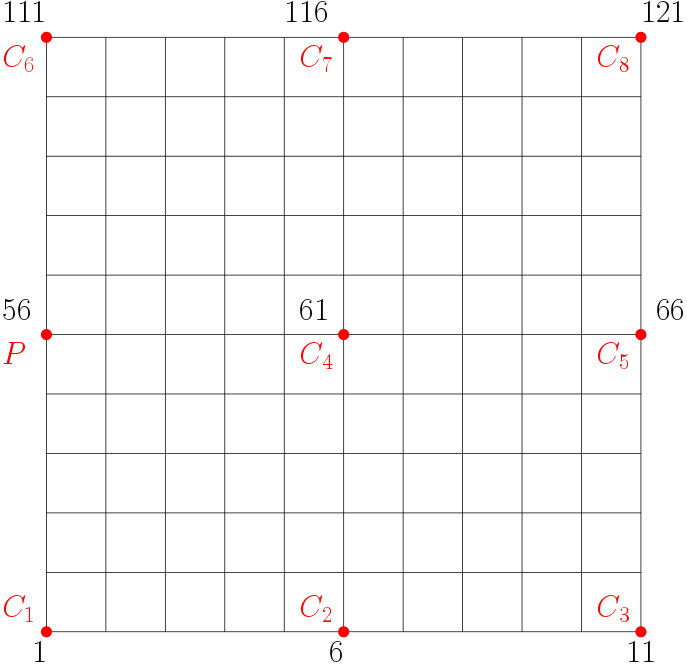

We introduce the parameters required by the block `N ports Nastran body` dialog box as done in the following figure:

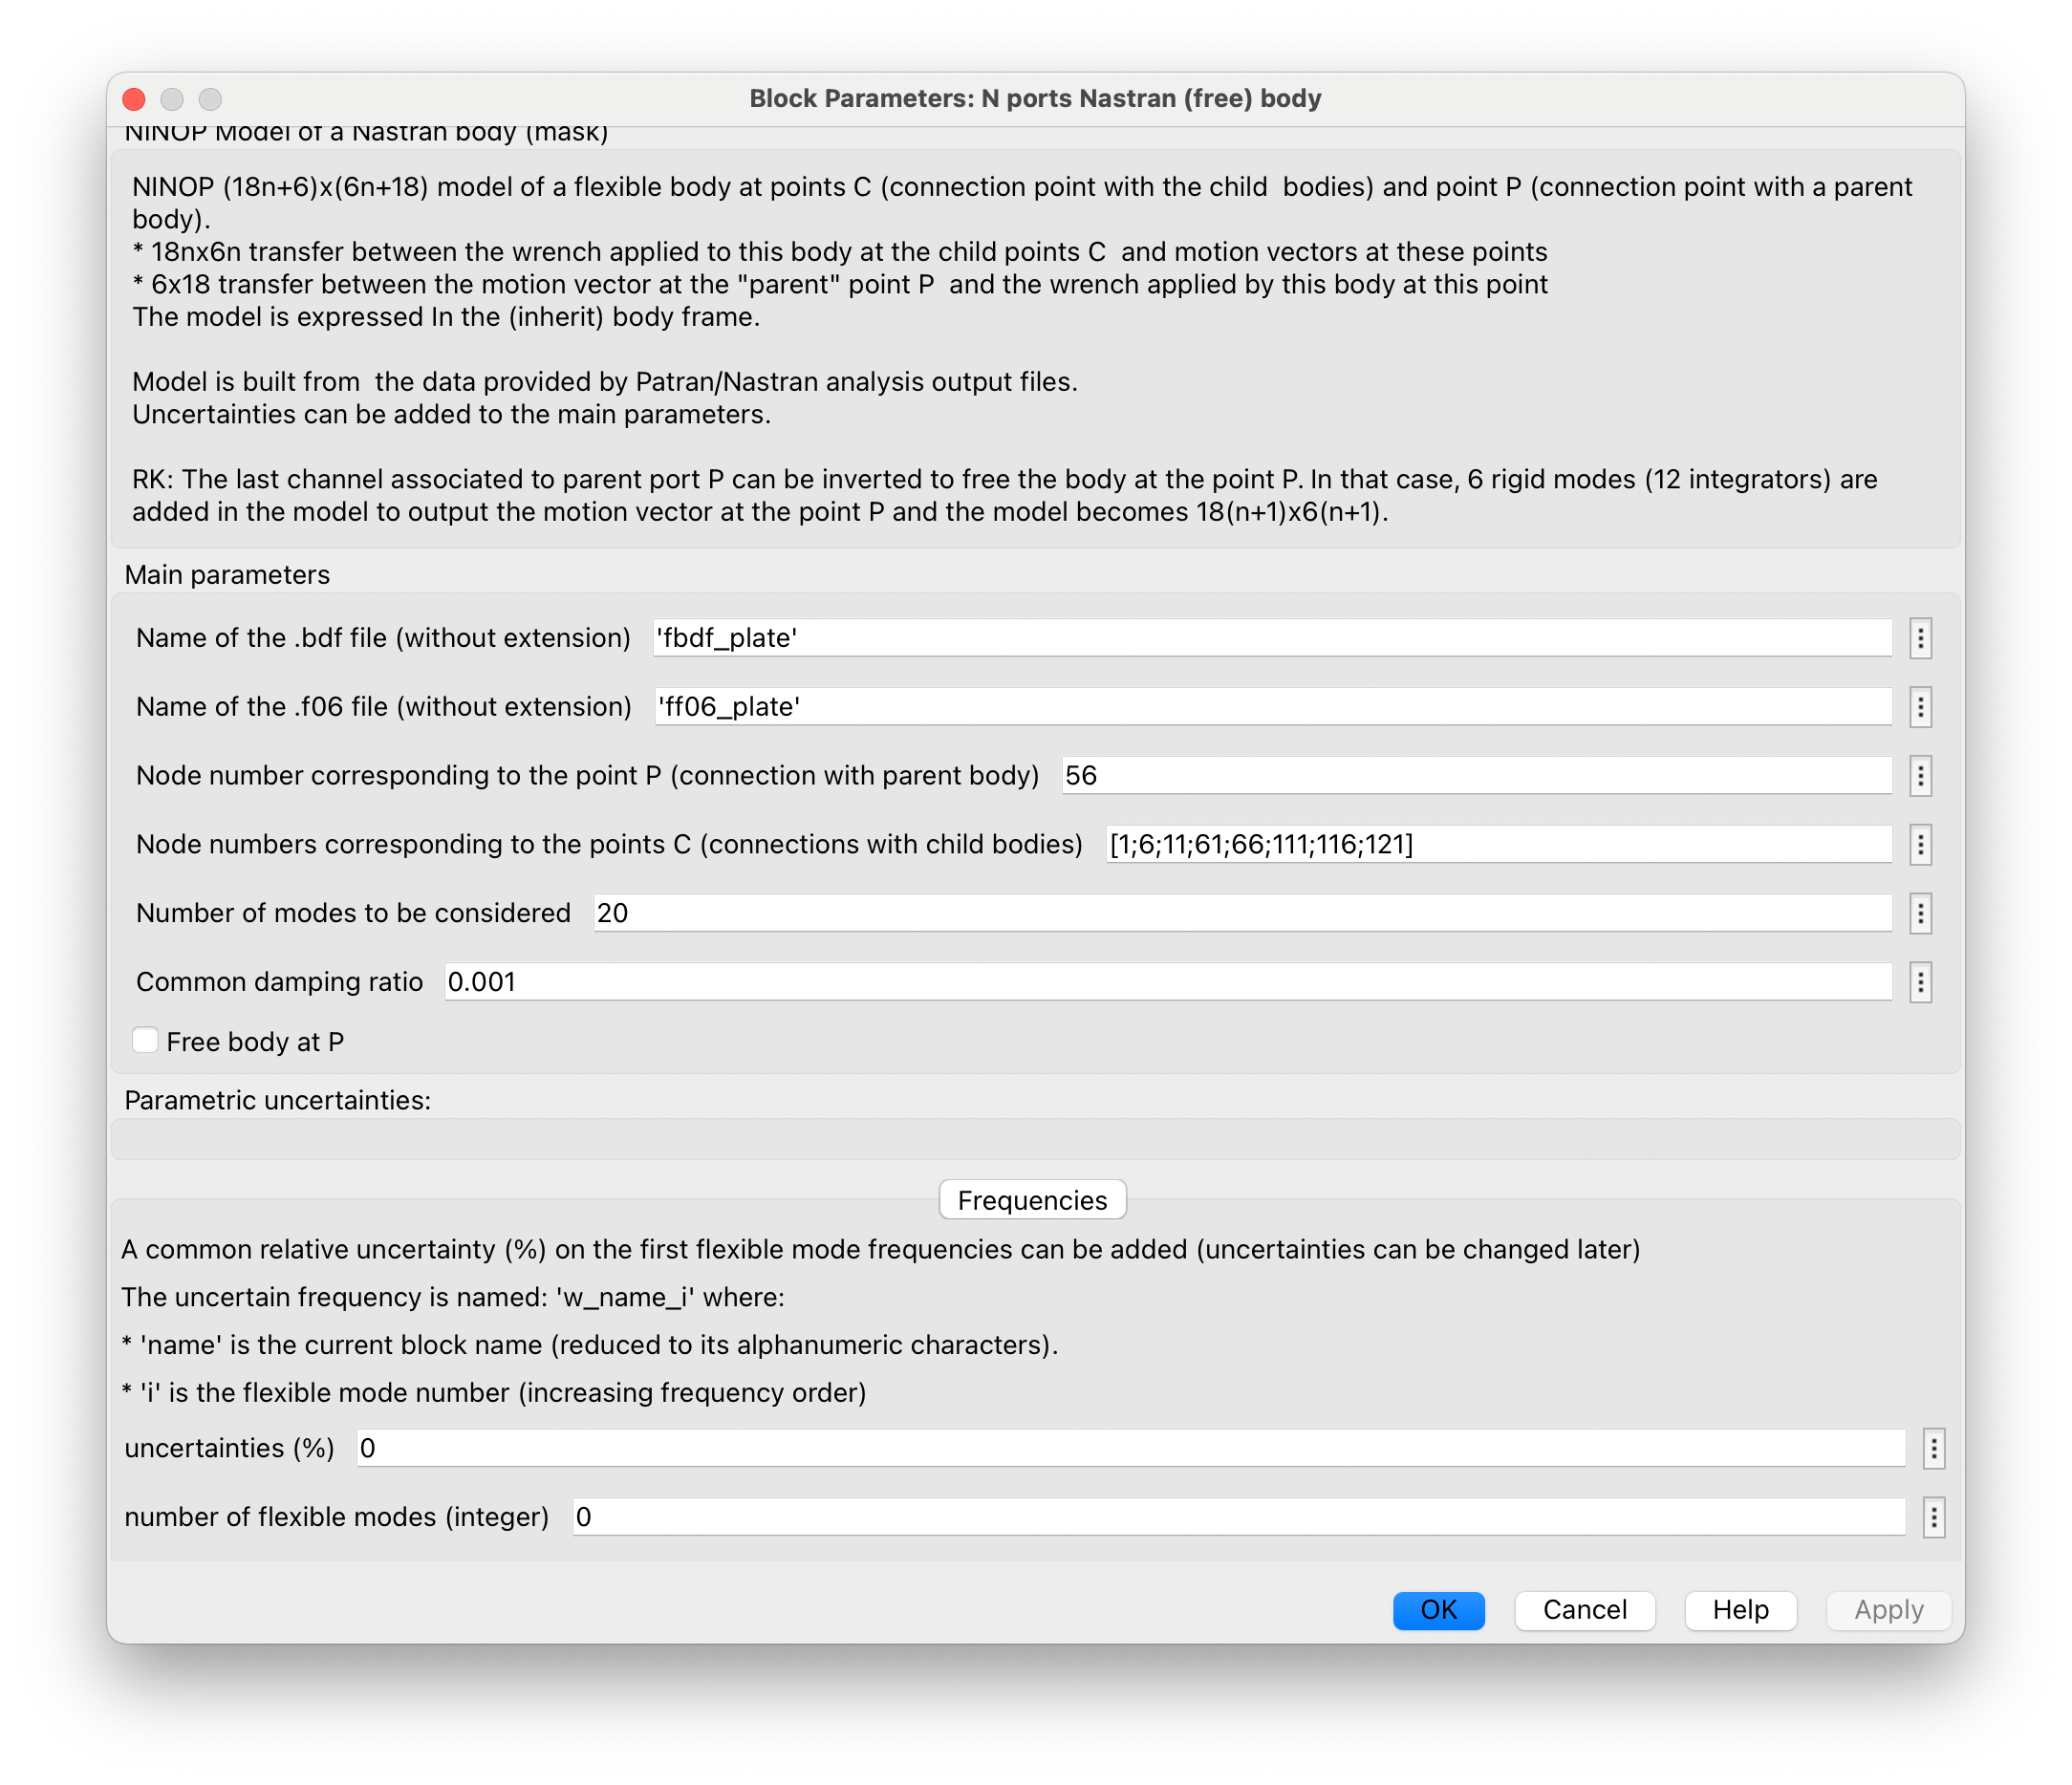

The reader is advised to read the inline help available in the dialog box (internet connection required), also available by:

web DocNPortNastranBody.html -new

## 3. SIMULATION

Once the `NASTRAN` NINOP model is ready we can use it for the needed applications. In the next DEMO we show for instance how to simulate the plate dynamics when subjected to an impulsive force acting at $t=0.5\,s$ on the point $C_3$ perpendicular to its face. The last figure depicted the plate deformation according to time (it can take several minutes, be patient...).

T_sim = 3;
pulse_width = 2; % Percentage of T_sim
amp_pulse = 1;
dt = 0.01;

% Integrator initial conditions on speed 
dot_x_0 = zeros(8*6,1);
% Integrator initial conditions on position 
x_0 = [zeros(6,1);...      %C1
       [.5 0 0 0 0 0]';... %C2
       [1 0 0 0 0 0]';...  %C3
       [.5 .5 0 0 0 0]';...%C4
       [1 .5 0 0 0 0]';... %C5
       [0 1 0 0 0 0]';...  %C6
       [.5 1 0 0 0 0]';... %C7
       [1 1 0 0 0 0]'];    %C8

The simulink file `clamped_plate_simulation.slx` for the simulation:

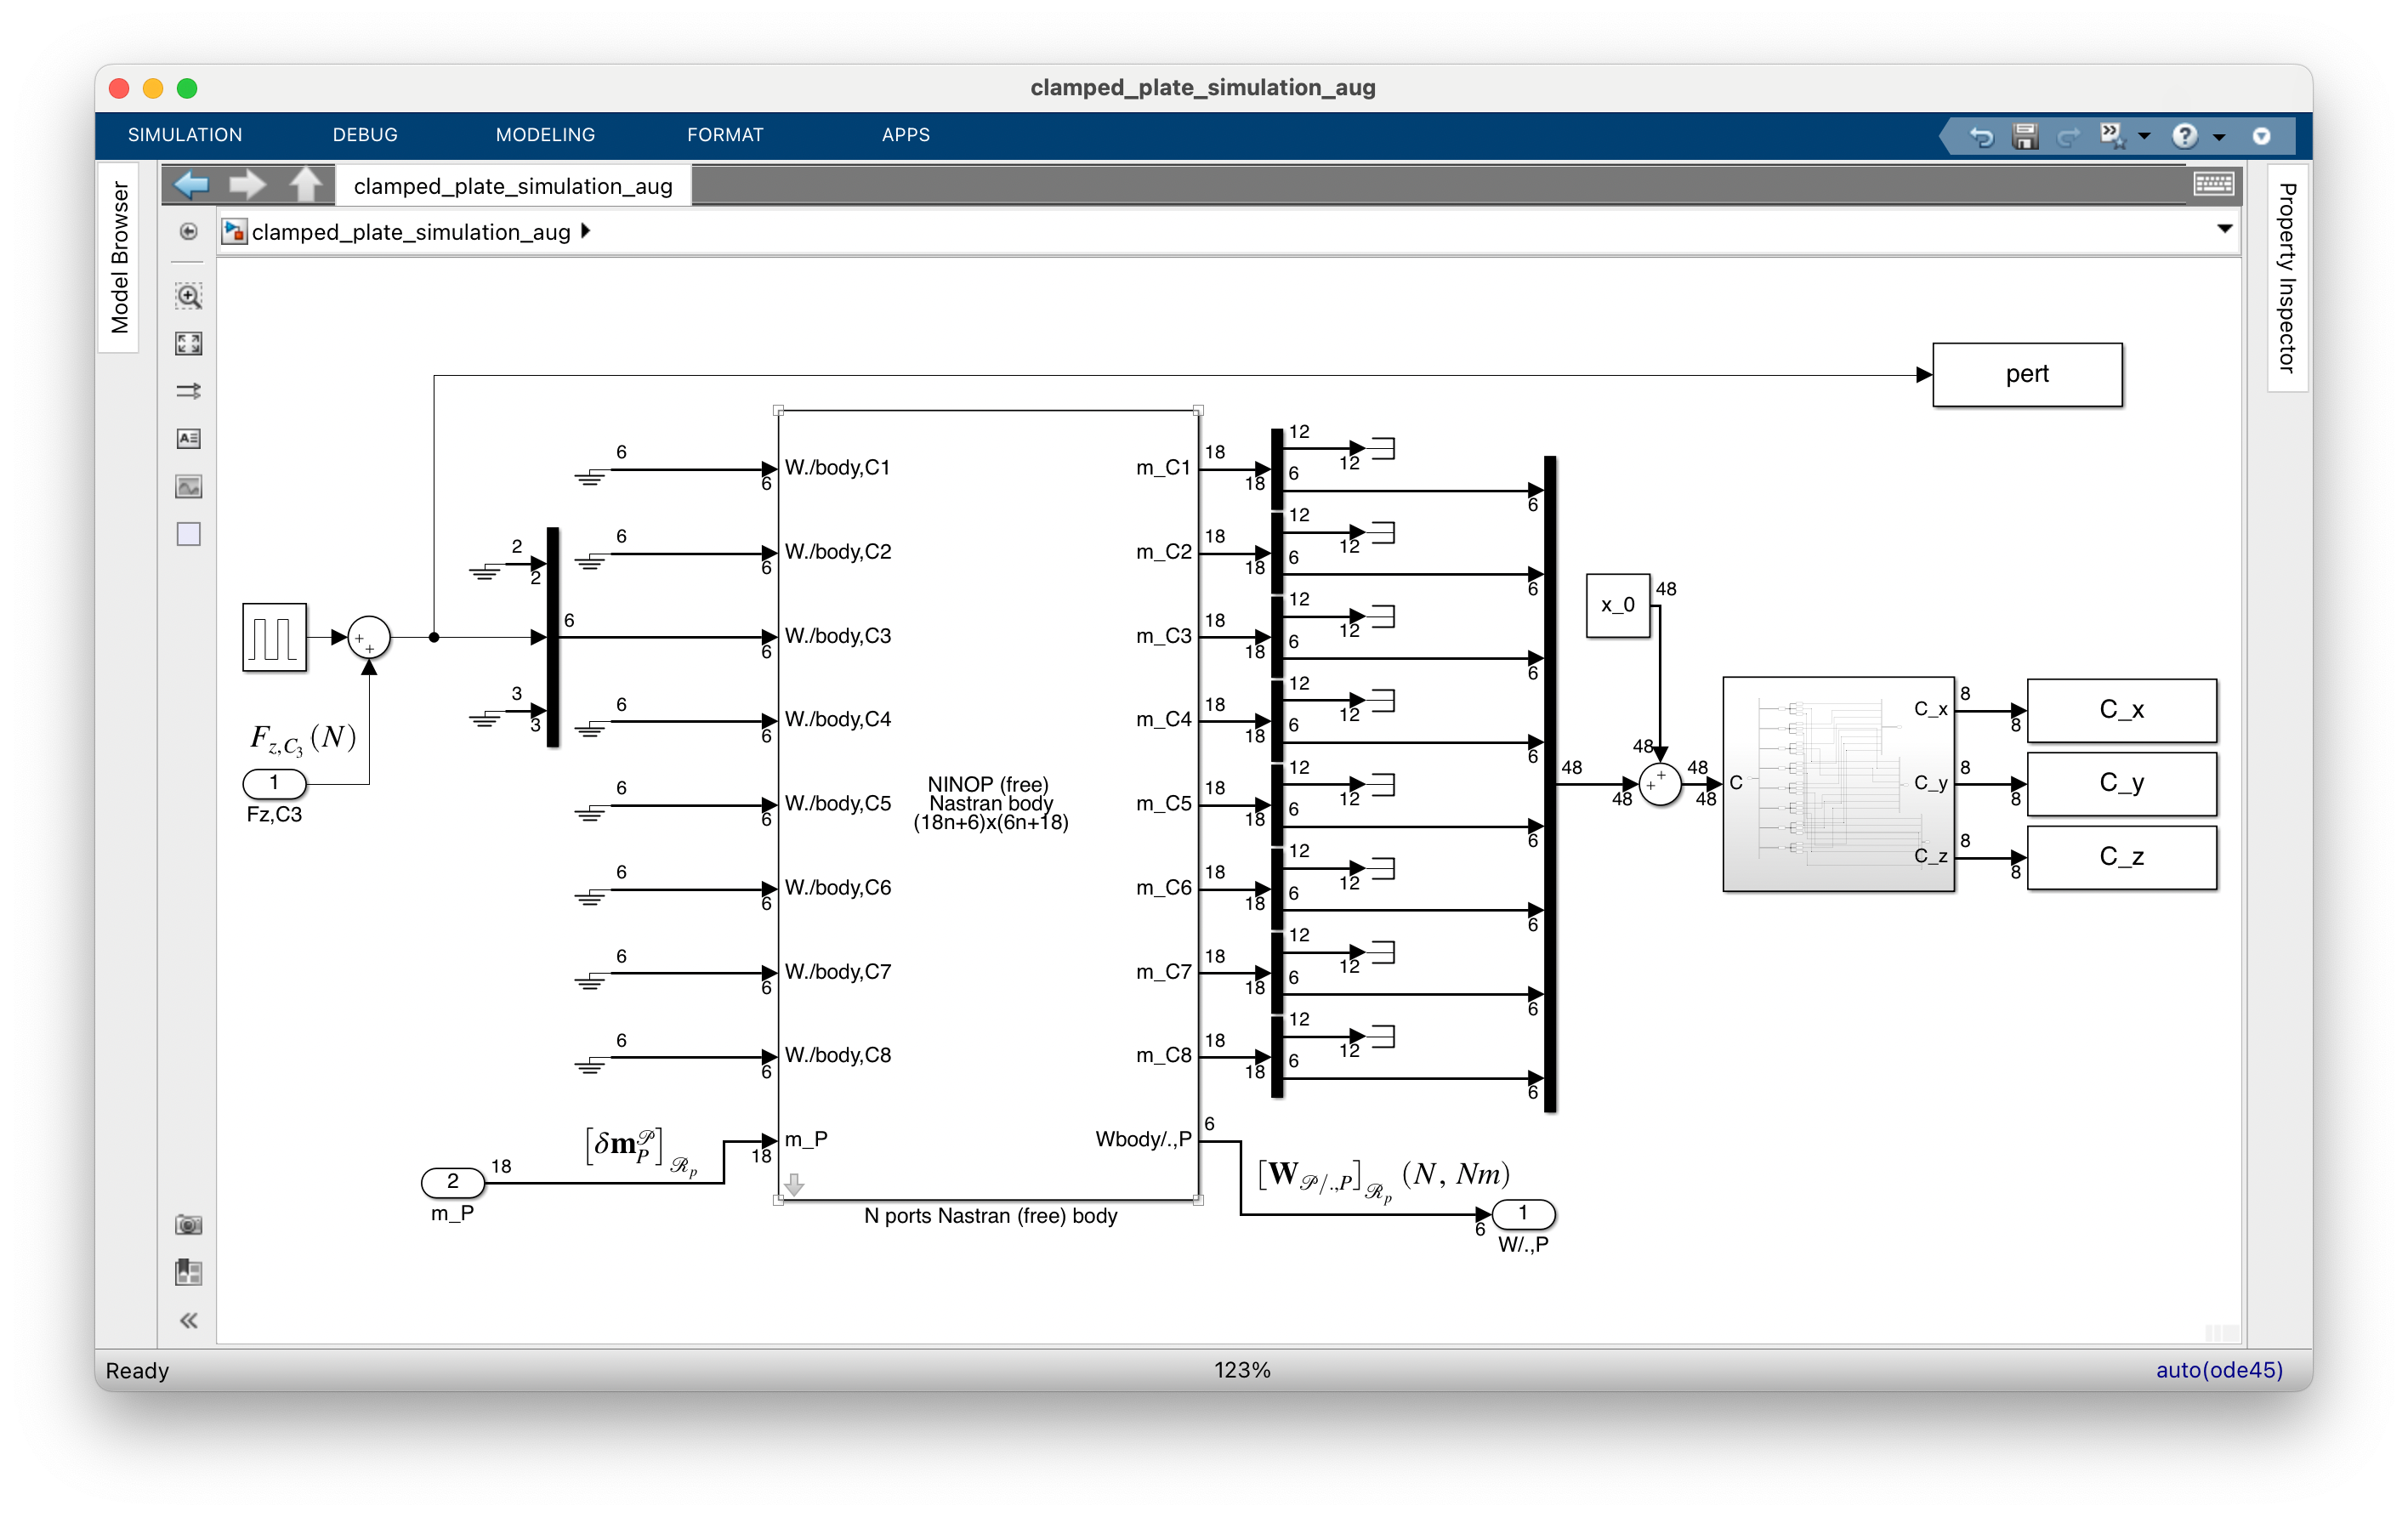

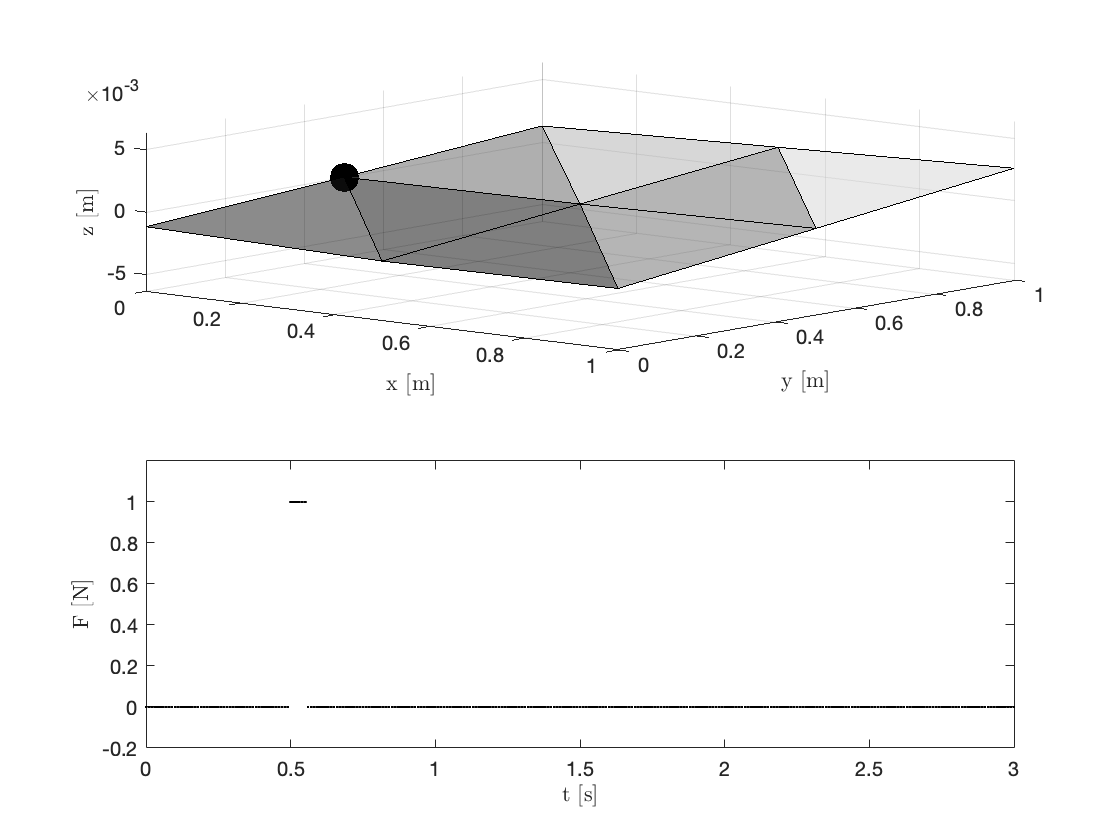

clamped_plate_simulation_aug
sim('clamped_plate_simulation_aug')
%%
N = length(C_x.time);
t = C_x.time;
X = [C_x.signals.values(:,1:3) zeros(N,1) C_x.signals.values(:,4:end)];
Y = [C_y.signals.values(:,1:3) .5.*ones(N,1) C_y.signals.values(:,4:end)];
Z = [C_z.signals.values(:,1:3) zeros(N,1) C_z.signals.values(:,4:end)];
f = figure;

axis([0 1 0 1 -1e-2 1e-2])
[Xs,Ys,Zs] = sphere;

for i = 1:N
    subplot(2,1,1)
    tri = delaunay(X(i,:),Y(i,:)); %x,y,z column vectors
    h = trisurf(tri,X(i,:),Y(i,:),Z(i,:));
        colormap(gray)
    alpha(.5)
    view(40,30)         % set viewpoint
    axis([0 1 0 1 -max(max(abs(Z)))*1.1 max(max(abs(Z)))*1.1])
    hold on
    plot3(0,.5,0,'.k','MarkerSize',50)
    if pert.signals.values(i) ~= 0
        hold on
            plot3([1 1],[0 0],[Z(i,5) Z(i,5)-.5e-2],'r-^')
        hold off
    end
    hold off
    xlabel('x [m]','Interpreter','latex')
    ylabel('y [m]','Interpreter','latex')
    zlabel('z [m]','Interpreter','latex')

    subplot(2,1,2)
    plot(t(i),pert.signals.values(i),'.k','MarkerSize',.5)
    xlabel('t [s]','Interpreter','latex')
    ylabel('F [N]','Interpreter','latex')
    hold on
    axis([0 t(end) -0.2 amp_pulse+.2])
    shg
    refresh(f)
    pause(1e-5)
end

## 4. Comparison of the plate models

The same cantilevered plate is used to compare the various plate models avalaible in the SDTlib:

- the Nastran model used as a reference model available thank to the block:  `N ports Nastran body,`

- the FEM (Finite Element Model) of a Kirchhoff plate available in the block: `multi-port FEM Kirchhoff plate`,

- the Kirchhoff plate model based on an analytical superelement available in the block: `multi-port flexible plate`.

Note that these last 2 blocks can be very usefull in case the user does not have access to `NASTRAN/PATRAN`. In addition: with these 2 blocks it is also possible to model the plate with several parent nodes (several clamped nodes).

The 3 simulink files using these 3 models are: `clamped_plate_NASTRAN.slx`, `clamped_plate_KIRCHHOFF_FEM.slx` and `clamped_plate_KIRCHHOFF_superelem.slx` and they all have the same inputs:

- the force $F_{z,C_3}$ ($N$) along $\mathbf z$-axis at point $C_3$,

- the [motion vector](matlab:open('../SDTfct/doc_SDTlib/doc_BODIES/doc_hub/DocGeneralNotations.html')) $\left[\delta\mathbf m^\mathcal P_P\right]_{\mathcal R_p}$  (18 components = 6 DoFs accelerations , 6 DoFs velocities and 6 DoFs positions) imposed to the plate $\mathcal P$ at the point $P$,

and the same ouput: the wrench $\left[\mathbf W_{\mathcal P/.,P}\right]_{\mathcal R_p}$ (6 components in $N$ and $Nm$)  applied by the plate $\mathcal P$ at the point $P$.

The comparison considers

- the DC-gain (with a $-$ sign) of the $6\times 6$ transfer from the 6 DoF acceleration  $\left[\ddot\mathbf x_P\right]_{\mathcal R_p}$ (the first $6$ component of the motion vector) to $\left[\mathbf W_{\mathcal P/.,P}\right]_{\mathcal R_p}$  to check the mass budget,

- the frequency domain responses of the 3 transfers from $F_{z,C_3}$ to $\left[\mathbf W_{\mathcal P/.,P}\right]_{\mathcal R_p}([3\;4\;5])$ i.e. the force along $\mathbf z$-axis, the torque arpound $\mathbf x$-axis and the torque around $\mathbf y$-axis applied by the plate to the bearing structure at the point $P$.

clamped_plate_NASTRAN_aug
M1=linearize('clamped_plate_NASTRAN_aug');
clamped_plate_KIRCHHOFF_FEM_aug
M2=linearize('clamped_plate_KIRCHHOFF_FEM_aug');

678 states removed


clamped_plate_KIRCHHOFF_superelem_aug
M3=linearize('clamped_plate_KIRCHHOFF_superelem_aug');
-dcgain(M1('W_P','Xddot_P'))

ans =     6.0474         0         0         0         0   -0.0000
         0    6.0474         0         0         0    3.0237
         0         0    6.0474    0.0000   -3.0237         0
         0         0    0.0000    0.5039    0.0000         0
         0         0   -3.0237    0.0000    2.0158         0
   -0.0000    3.0237         0         0         0    2.5198


-dcgain(M2('W_P','Xddot_P'))

ans =     6.0474         0         0         0         0         0
         0    6.0474         0         0         0    3.0237
         0         0    6.0474   -0.0000   -3.0237         0
         0         0   -0.0000    0.5040    0.0000         0
         0         0   -3.0237    0.0000    2.0158         0
         0    3.0237         0         0         0    2.5197


-dcgain(M3('W_P','Xddot_P'))

ans =     6.0474         0         0         0         0         0
         0    6.0474         0         0         0    3.0237
         0         0    6.0474   -0.0000   -3.0237         0
         0         0   -0.0000    0.5040    0.0000         0
         0         0   -3.0237    0.0000    2.0158         0
         0    3.0237         0         0         0    2.5197


One can check that the total rigid mass, inertia, centering are the same for the models. 

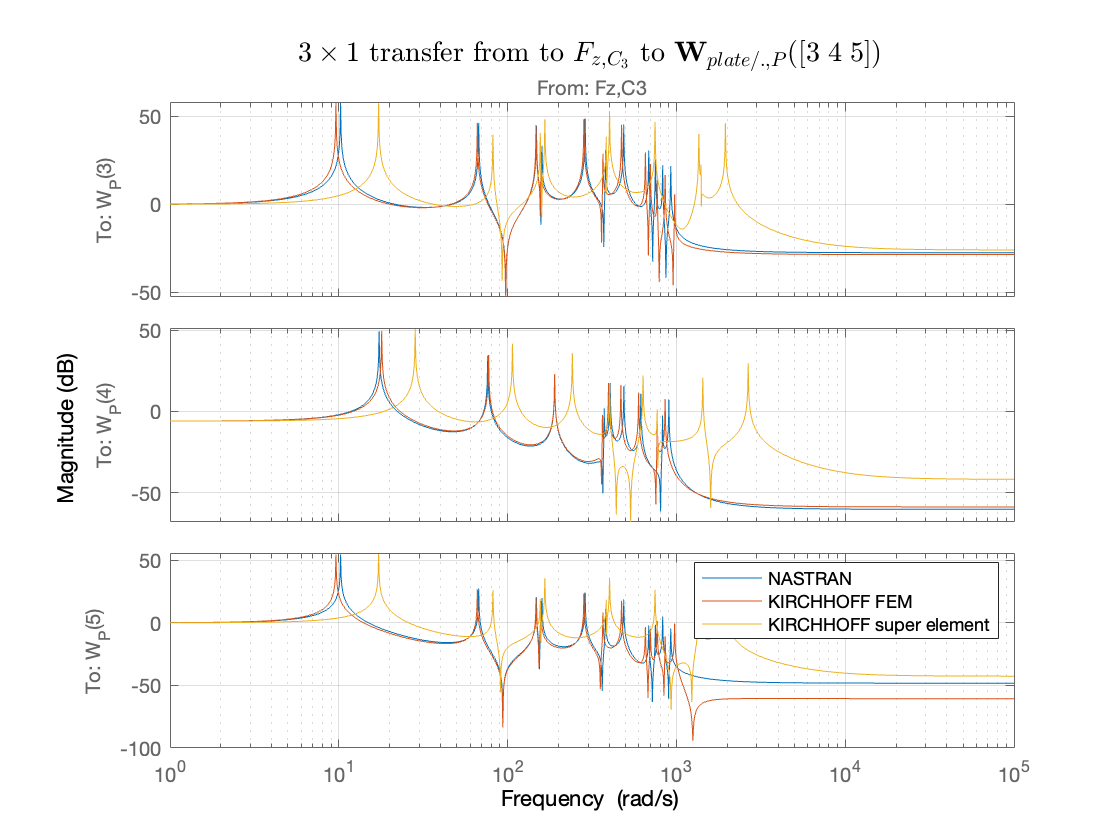

figure
bodemag(M1([3 4 5],1),M2([3 4 5],1),M3([3 4 5],1))
legend('NASTRAN','KIRCHHOFF FEM','KIRCHHOFF super element')
grid
warning('off')
title('$3\times 1$ transfer from to $F_{z,C_3}$ to $\mathbf W_{plate/.,P}([3\;4\;5])$','Interpreter','latex','FontSize',14);

**Conclusion:** the KIRCHHOFF FEM model and the NASTRAN model have a very good matching while the KIRCHHOFF superelement  over-estimated the frequency of the first flexible modes.